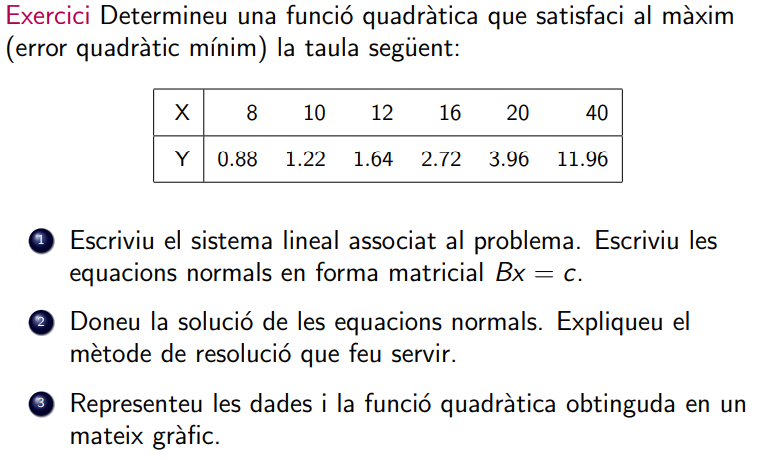

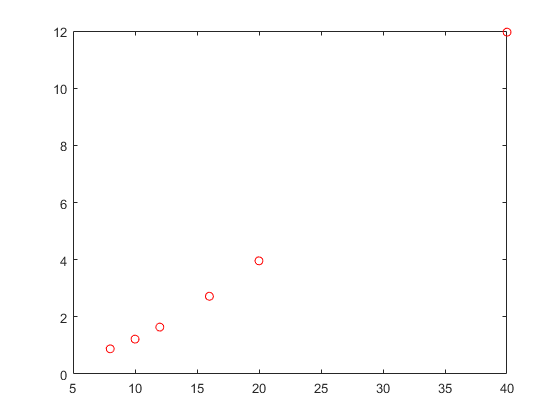

% dades
x = [8 10 12 16 20 40]';
y = [0.88 1.22 1.64 2.72 3.96 11.96]';
plot(x,y, 'ro');

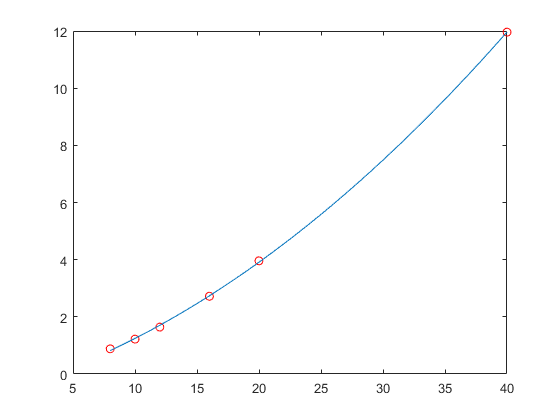


% Sistema
A = [x.^2 x ones(size(x,1), 1)]; b = y;

% Resolucio per ecuacions normals
coef = A'*A \ A'*b;

% Grafica
z = 8:40;
pz = polyval(coef,z);
plot(x,y,'ro',z,pz),